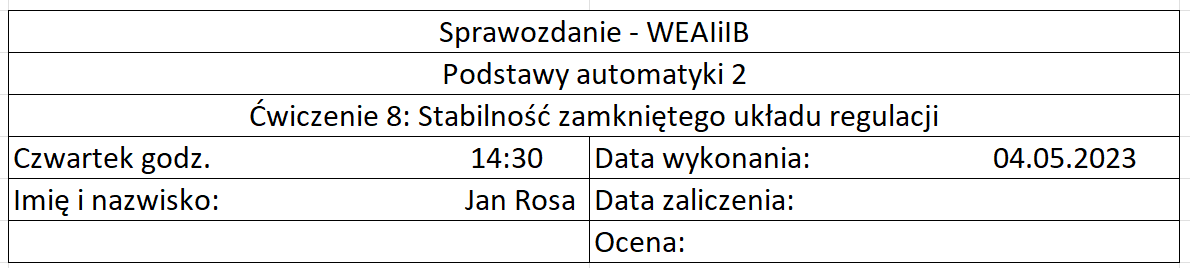

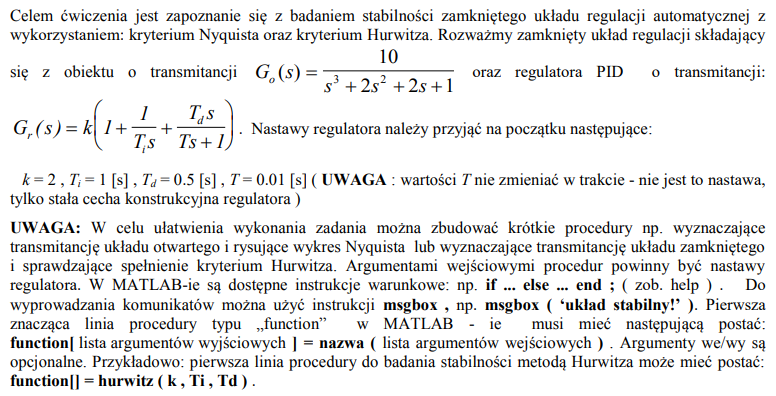

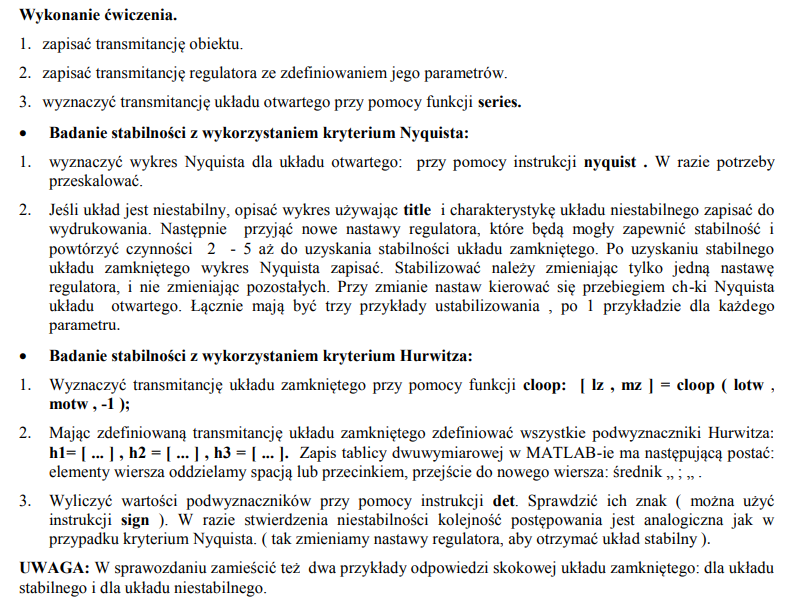

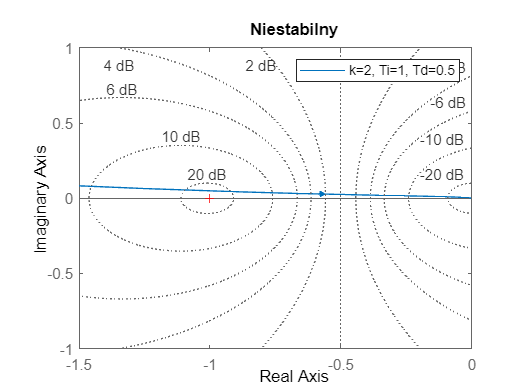

obiekt = tf([0 0 0 10],[1 2 2 1]);
k = 2; Ti = 1; Td = 0.5;


nquist(obiekt, k, Ti, Td, 0, [-1.5, 0, -1, 1]);

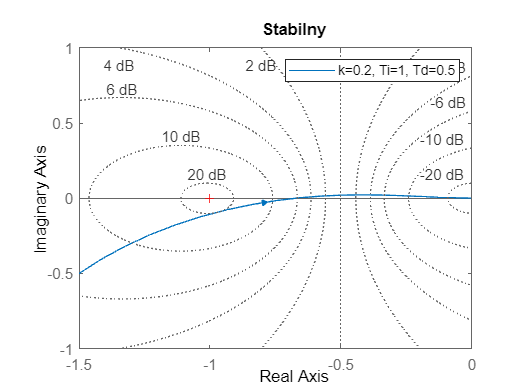

nquist(obiekt, k/10, Ti, Td, 1, [-1.5, 0, -1, 1]);

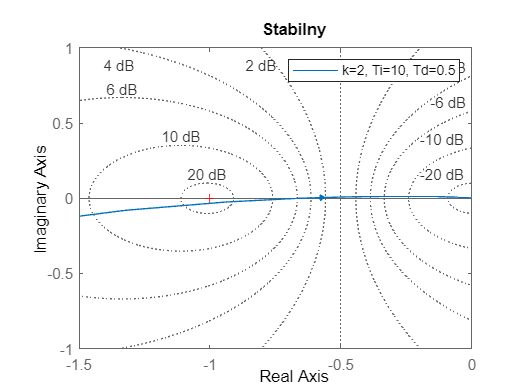

nquist(obiekt, k, Ti*10, Td, 1, [-1.5, 0, -1, 1]);

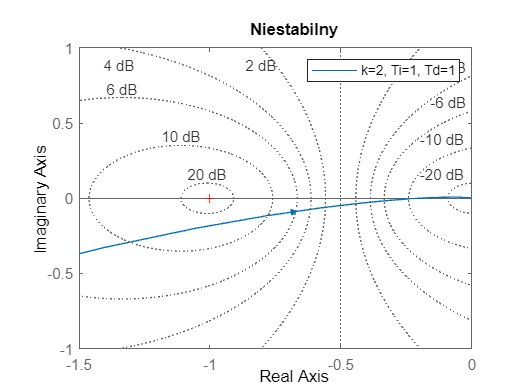

nquist(obiekt, k, Ti, Td*2, 0, [-1.5, 0, -1, 1]);

hrwidz(obiekt, k, Ti, Td)

function [] = nquist(obiekt, k, Ti, Td, stb, ax)
    T = 0.01;
    reg = k*(1 + tf([0 1],[Ti, 0]) + tf([Td 0],[T 1]));
    obiektotw = series(obiekt,reg);
    figure;
    n = nyquistplot(obiektotw);
    opt = getoptions(n);
    opt.ShowFullContour = 'off';
    setoptions(n, opt);
    if stb
        title("Stabilny");
    else
        title("Niestabilny");
    end
    axis(ax)
    legend("k=" + string(k) + ", Ti=" + string(Ti) + ", Td=" + string(Td));
    grid on;

end

function [isstb] = hrwidz(obiekt, k, Ti, Td)
    T = 0.01;
    reg = k*(1 + tf([0 1],[Ti, 0]) + tf([Td 0],[T 1]));
    [num, den] = tfdata(series(obiekt, reg));
    [lz, mz] = cloop(cell2mat(num), cell2mat(den), -1);
    H1 = [mz(2)];
    H2 = [mz(2) mz(4); mz(1), mz(3)];
    H3 = [mz(2), mz(4), mz(6); mz(1), mz(3), mz(5); 0 mz(2), mz(4)];
    H4 = [mz(2), mz(4), mz(6), 0;
        mz(1), mz(3), mz(5), 0;
        0 mz(2), mz(4), mz(6);
        0 mz(1), mz(3), mz(5)];

    H1 = sign(det(H1));
    H2 = sign(det(H2));
    H3 = sign(det(H3));
    H4 = sign(det(H4));
    isstb = (H1>0)*(H2>0)*(H3>0)*(H4>0);
    if 1
        figure;
        step((obiekt*reg/(1+obiekt*reg)))
        
        if(isstb)
            title("Stabilny")
        else
            title("Niesabilny")
        end
        legend("k=" + string(k) + ", Ti=" + string(Ti) + ", Td=" + string(Td));
        grid on;
    end
end
